[Эта версия не интерактивна, см. КОД для матлаба](https://github.com/ne-umnepatop/PraktLinAlg/tree/main/%D0%9B%D0%B0%D0%B1%D0%BE%D1%80%D0%B0%D1%82%D0%BE%D1%80%D0%BD%D0%B0%D1%8F%20%D1%80%D0%B0%D0%B1%D0%BE%D1%82%D0%B0%203). Кто будет запускать, сначала запускаяте танк, потом код, не очищая Workspace.

## Почувствовав прилив творческих сил, создал куб

    Использовал листинг 1, код комментировал, чтобы ближе к строкам быть

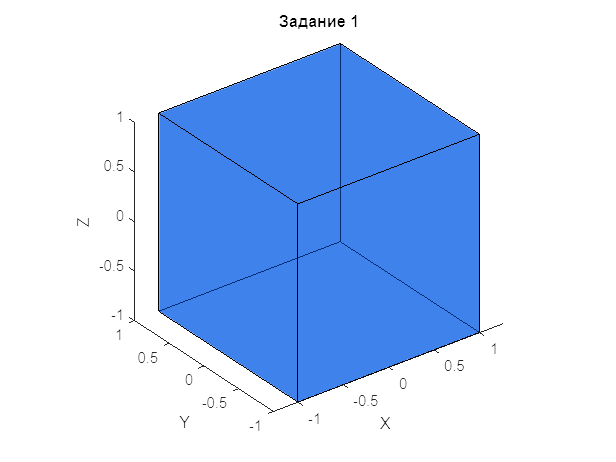

Cube = [-1, 1, 1,-1,-1, 1, 1 ,-1;
-1,-1, 1, 1,-1,-1, 1, 1;
-1,-1,-1,-1, 1, 1, 1, 1;
1, 1, 1, 1, 1, 1, 1, 1];
% если что, выше задаются вершины
facesCube = [1, 2, 6, 5;
2, 3, 7, 6;
3, 4, 8, 7;
4, 1, 5, 8;
1, 2, 3, 4;
5, 6, 7, 8];
% тут грани в виде 4 вершин на краях
blue = [0,0.35,0.9,0.5]; % цвет куба ДО преобразований
rgba = [1,0.5,0, 0.5]; % хочу мой фирменный оранжевый для стиля ПОСЛЕ преобразования
bllk=[0.2,0.2,0.2,0.5];greeen=[0,0.4,0,0.5];
title('Задание 1');Dshow ( Cube , facesCube , blue ) % вызвали отрисовку

    Тут следовало бы поразмыслить, для каких таких целей нам 4-я координата в кубе. Вначале очевидно посмотерть на код, увидеть *vertices (1:3 ,:) ./ vertices (4 ,:))'*, тщательно подумать, что такое поэлементное деление первых трёх, которые как раз задают координаты на 4, и понять для начала, что если в 4 не единица, то точка единичного куба не будет в единицах, то есть, когда будет нарисована повехность, она окажется наклонённой (если менять не на одно и то же число во всех коориднатах) (так я сначала узнал координаты танковых запчастей); второе, о чём подумает трезвый человек: это для масштабирования и регулирования чувствительности, мол, разделим на 0,5 и вот он в два раза больше, а про чувствительность см. низ третьего задания; ну а третье, что можно понять, если начать читать мелкий курсивный шрифт в самом начале описания лабораторной, то можно понять, что это для тех, кто умеет только умножать, но не складывать векторы или выпендривается своими гомогенными координатами.

    Также отмечу, что использую полупрозрачные цвета для того, чтобы повысить наглядность.

    Вообще, не зря же я старался, держите танк (он же задание 8): 

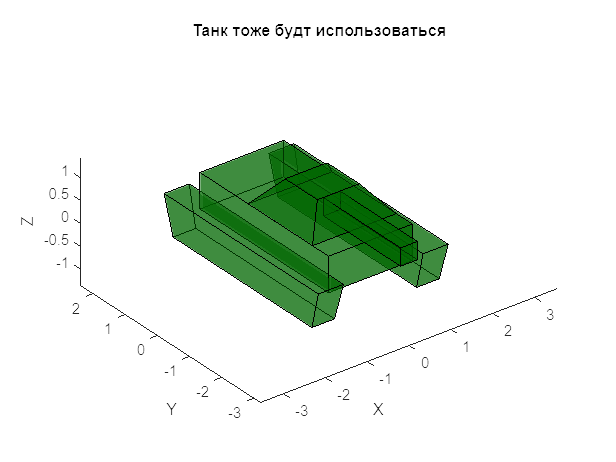

clf;title('Танк тоже будт использоваться');Dshow ( TANK , faces , greeen );

Как создавался танк можно посмотреть [по ссылке](https://github.com/ne-umnepatop/PraktLinAlg/tree/main/%D0%9B%D0%B0%D0%B1%D0%BE%D1%80%D0%B0%D1%82%D0%BE%D1%80%D0%BD%D0%B0%D1%8F%20%D1%80%D0%B0%D0%B1%D0%BE%D1%82%D0%B0%203). 

## Куб - это хорошо, но мало

    Теперь мне предстояло расшириться, ведь куб - это лишь куб, но бОльший куб даст бОльшие возможности, например, если увеличисть куб в pi раз, мы почувствуем, что это совсем нетривиально, а значит мы смелы и сильны.

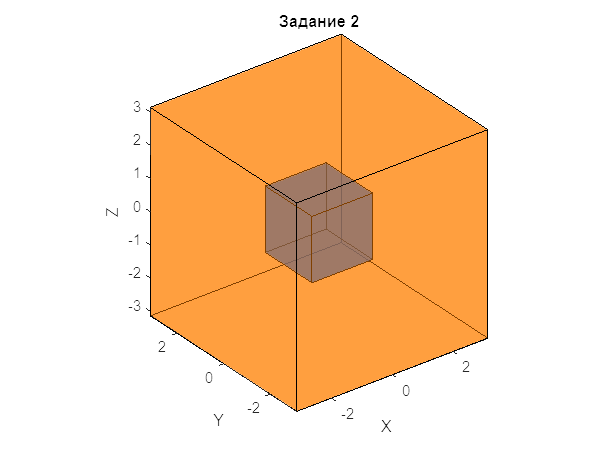

clf;A2=[pi,0,0,0;
    0,pi,0,0;
    0,0,pi,0;
    0,0,0,1];
Cube2 = A2 * Cube; % матрицу перехода на каждую строку
title('Задание 2');
Dshow ( Cube , facesCube , blue)
Dshow ( Cube2 , facesCube , rgba)

    Это, конечно, круто, но до жути банально. Поступим ка кнастоящие панки, и изменим масштаб другой матрицей, а то из куба получать куб...

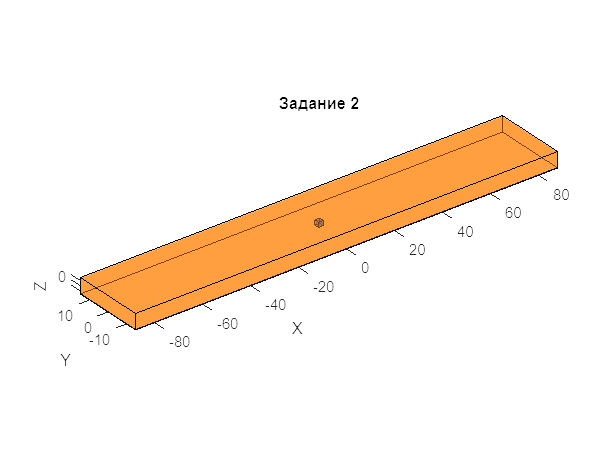

A21=[
    88,0,0,0;
    0,15,0,0;
    0,0,pi,0;
    0,0,0,1];
Cube21 = A21 * Cube;clf;
title('Задание 2');

Dshow ( Cube , facesCube , blue );Dshow ( Cube21 , facesCube , rgba);

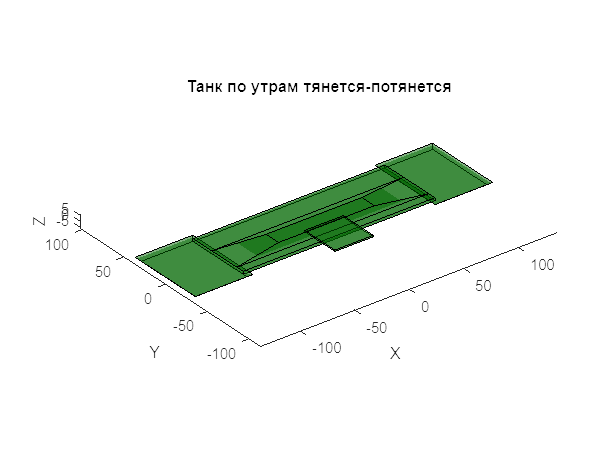

clf;title('Танк по утрам тянется-потянется');Dshow ( A21 *TANK , faces , greeen );

## Куб стал таким большим, что загораживает проход, его нужно сместить

    Для этих целей решение крайне простое: взять и сдвинуть. Сдвигать буду большой куб из второго задания, и на пи. Куб до преобразований всегда синий, после - оранжевый. 

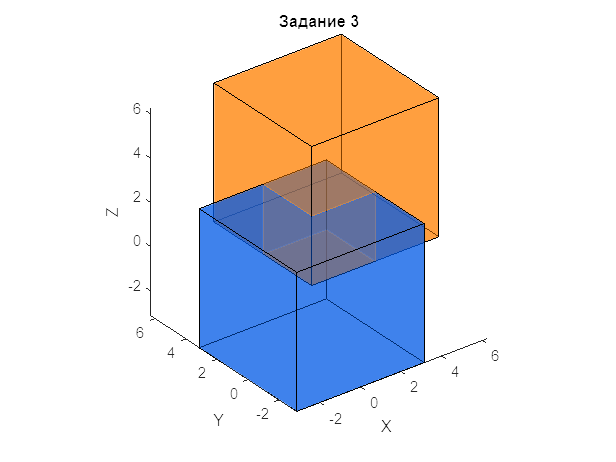

A3=[pi;pi;pi;0];
Cube3 = Cube2 + A3; clf;
title('Задание 3');
Dshow ( Cube2 , facesCube , blue);Dshow ( Cube3 , facesCube , rgba);

    При этом дальняя вершина куба, которая после второго задания оказалась в -pi по всем координатам, переместится в начало координат, то есть у куба все координаты станут неотрицательными.

    Конечно, можно задать и умножением матриц, для чего, собственно, и дана нам четвертая координата, которую поначалу легко принять за пятую ногу. Далее я покажу, как будет выглядеть умножение, но только в одном примере просто потому, что считаю сложение матриц, во-первых, более интуитивной оперцией, во-вторых, более дешёвой для ресурсов компа, которые все и напрочь скушал матлаб, с другой же стороны, путём умножения нескольких матриц получится изменть состояние только тогда, когда мы двигаем именно умножая на матрицу.

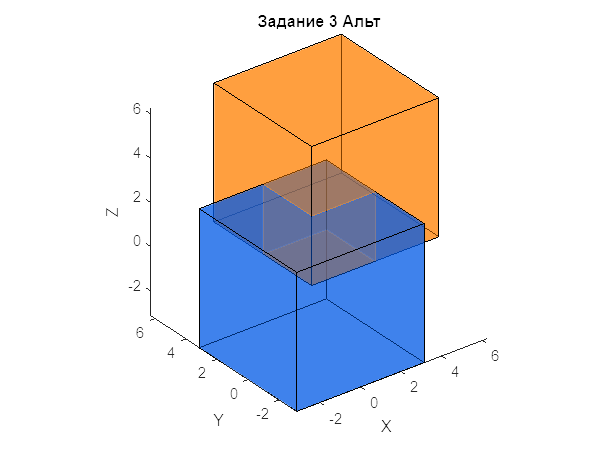

A30=[1,0,0,pi;
    0,1,0,pi;
    0,0,1,pi;
    0,0,0,1];
Cube30 = A30*Cube2; clf;
title('Задание 3 Альт');
Dshow ( Cube2 , facesCube , blue);
Dshow ( Cube30 , facesCube , rgba);

    Как видим, результат "внезапно" одинаковый. Так что далее, как более понятный с точки зрения прочтения способ, буду суммировать с вектором смщения, но мы (я и мои внимательные лучшие читатели) подразумеваем, что это точно с тем же эффектом можно сделать умножением.

    Но это снова не так интересно, ведь так мы долго будем лететь до Марса. Чтобы приземлиться прямёхонько туда, возьмем новую мтарицу, и сместим дальше до 2035 года.

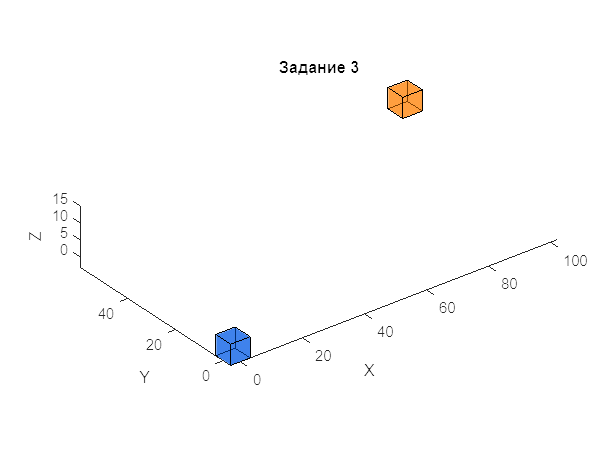

A31=[
    99;
    56.8;
    12;
    0];
Cube31 = Cube2 + A31;clf;
title('Задание 3');

Dshow ( Cube2 , facesCube , blue);
Dshow ( Cube31 , facesCube , rgba);

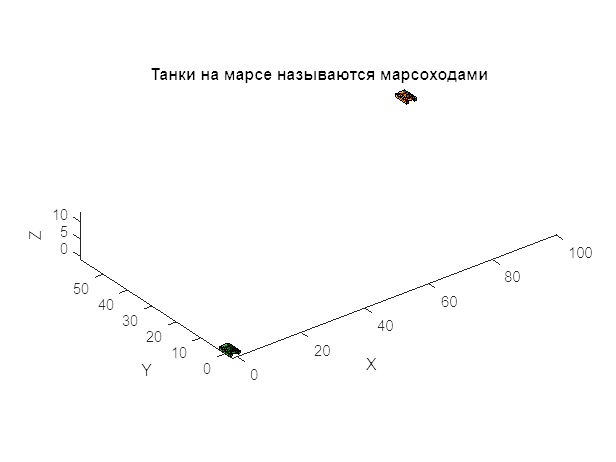

clf;title('Танки на марсе называются марсоходами');Dshow ( TANK , faces ,greeen );Dshow ( TANK + A31 , faces , rgba );

    Совсем другое дело! Более того, из-за такого расстояния размерами теперь можно пренебречь, и вот она, задачка про материальные точки из курса школьной физики. Хотя я потом посмотрел на результат и, для наглядности, 9999 и 568 заменил на 99 и 56,8.

    Заодно покажу, что я имел ввиду под тем, что 4-я координата регулирует чувствительность (как задан зелёный куб см. ниже):

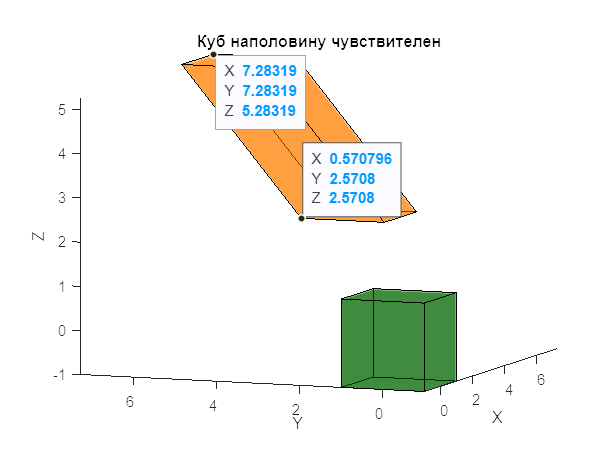

PsevdoCube = [
-0.5, 0.5, 0.5,-0.5,-2, 2, 2 ,-2;
-0.5,-0.5, 0.5, 0.5,-2,-2, 2, 2;
-0.5,-0.5,-0.5,-0.5, 2, 2, 2, 2;
0.5, 0.5, 0.5, 0.5, 2, 2, 2, 2];
clf;title('Куб наполовину чувствителен');Dshow ( PsevdoCube , facesCube ,greeen );
Dshow ( PsevdoCube + A3 , facesCube , rgba );view([-68.75 7.20]);ax7 = gca;
chart7 = ax7.Children(1);datatip(chart7,7.283,7.283,5.283);datatip(chart7,2.571,2.571,2.571);

Как видно из предыдущих строк, то, что выглядит как (зеленым) куб, оказывается кубом далеко не во всех преобразованиях.

## Подул ветер, и куб завертелся

    Использую матрицу преобразования для поворота кубика. Три. Именно столько видов независимых возможных вращений может существовать в 3D пространстве. Вокург Ох, Оу, Оz. Если добавить к ним смещение по этим же осям, мы получим 6. Это число так и называют: 6 степеней свободы. Поворотам соответствуют матрицы, состоящие из блока обычной матрицы поворота 2х2, значения cos в которой расположены на главной диагонали матрицы поворота 3х3, также на этой диагонали находится 1, ярко выражающая отстутствие преобразований по той оси, координаты по которой не меняются. Далее пойдет несколько примеров, по которым легко понять, что именно происходит.

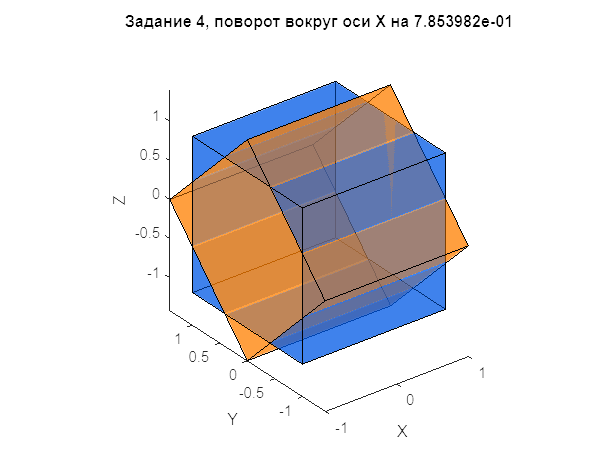

alpha = pi/4;
A4X=[
    1,0,0,0;
    0,cos(alpha),-sin(alpha),0;
    0,sin(alpha),cos(alpha),0;
    0,0,0,1];
A4Y=[
    cos(alpha) 0,-sin(alpha),0;
    0,1,0,0;
    sin(alpha),0,cos(alpha),0;
    0,0,0,1];
A4Z=[
    cos(alpha),-sin(alpha),0,0;
    sin(alpha),cos(alpha),0,0;
    0,0,1,0;
    0,0,0,1];
Cube4 = A4X * Cube;clf;
title(sprintf('Задание 4, поворот вокруг оси Х на %d', alpha));

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

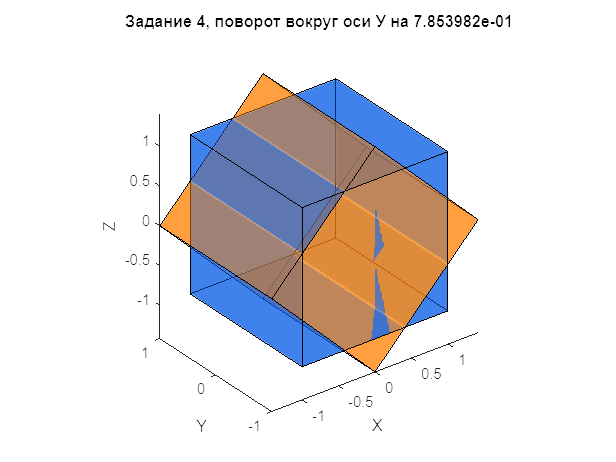

Cube4 = A4Y * Cube;clf;
title(sprintf('Задание 4, поворот вокруг оси У на %d', alpha));

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

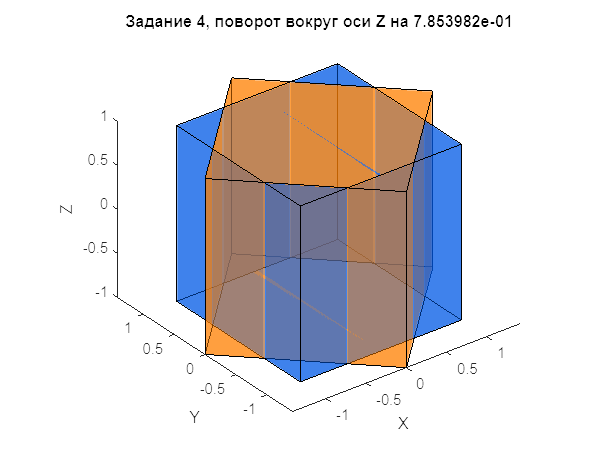

Cube4 = A4Z * Cube; clf;
title(sprintf('Задание 4, поворот вокруг оси Z на %d', alpha));

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

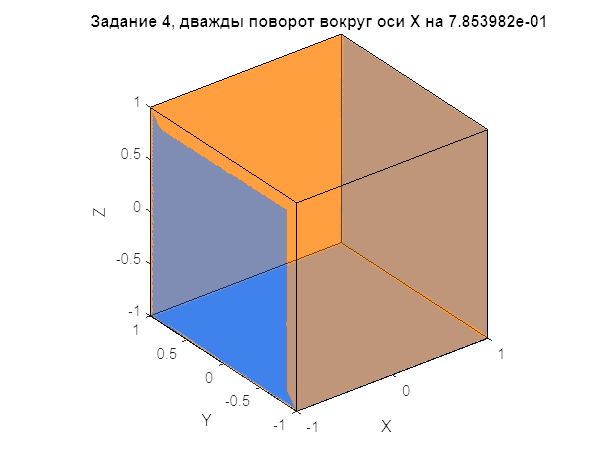

Cube4 = A4X *A4X * Cube;clf;
title(sprintf('Задание 4, дважды поворот вокруг оси Х на %d', alpha));

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

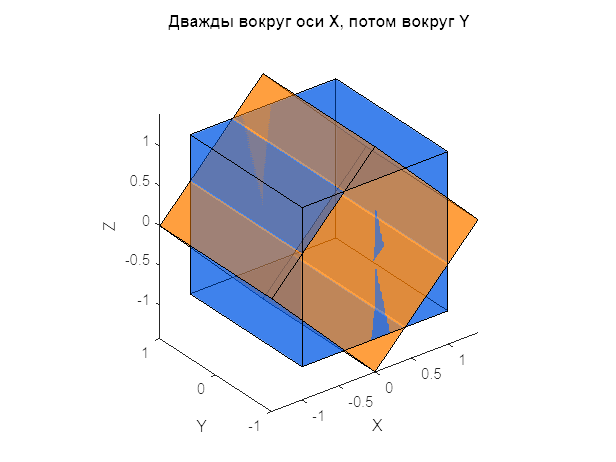

Cube4 = A4Y * A4X * A4X * Cube;clf;
title('Дважды вокруг оси X, потом вокруг Y');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

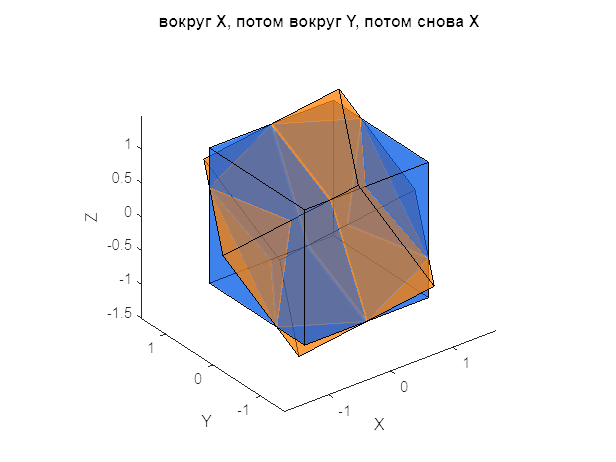

Cube4 = A4X * A4Y * A4X * Cube;clf;
title('вокруг X, потом вокруг Y, потом снова Х');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

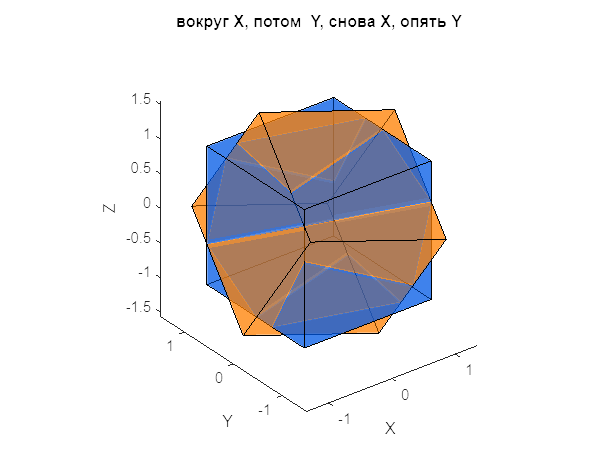

Cube4 = A4Y * A4X * A4Y * A4X * Cube;clf;
title('вокруг X, потом  Y, снова Х, опять Y');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

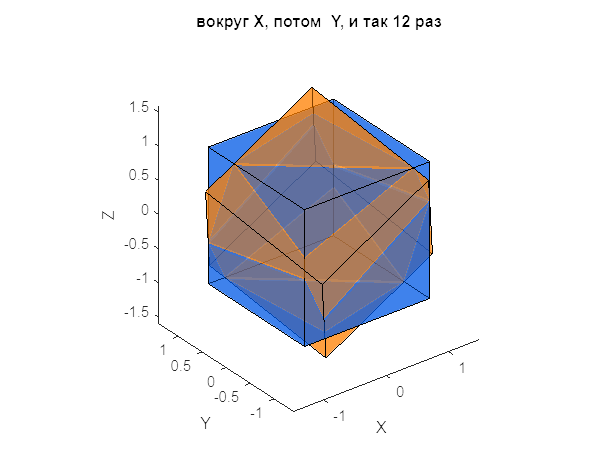

Cube4 = A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * Cube;clf;
title('вокруг X, потом  Y, и так 12 раз');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

Заметно, что мы так и не пришли в исходное состояние. Это легко представить, разложив сложный поворот по действиям:

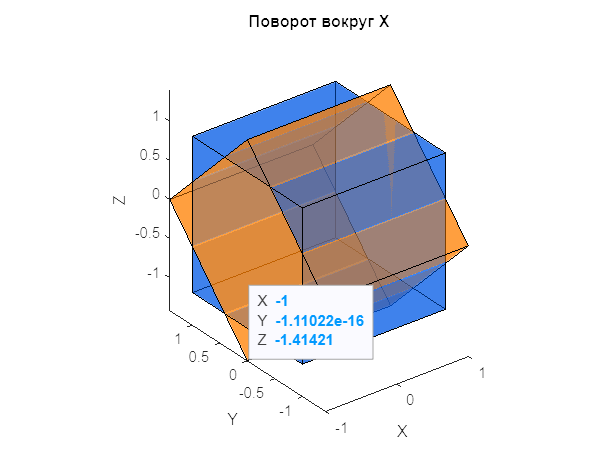

Cube4 = A4X * Cube;clf;
title('Поворот вокруг Х');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);
ax5 = gca;
chart5 = ax5.Children(1);
datatip(chart5,-1,0,-1.4);
chart5 = ax5.Children(2);
datatip(chart5,-1,1,-1);

Cube4

Cube4 =    -1.0000    1.0000    1.0000   -1.0000   -1.0000    1.0000    1.0000   -1.0000
   -0.0000   -0.0000    1.4142    1.4142   -1.4142   -1.4142    0.0000    0.0000
   -1.4142   -1.4142   -0.0000   -0.0000    0.0000    0.0000    1.4142    1.4142
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


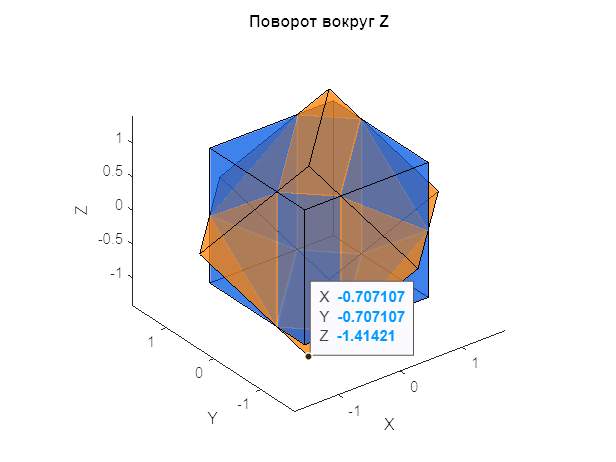

Cube4 = A4Z * Cube4;clf;
title('Поворот вокруг Z');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);
ax5 = gca;
chart5 = ax5.Children(1);
datatip(chart5,-sin(alpha),-sin(alpha),-1.4);

Cube4

Cube4 =    -0.7071    0.7071   -0.2929   -1.7071    0.2929    1.7071    0.7071   -0.7071
   -0.7071    0.7071    1.7071    0.2929   -1.7071   -0.2929    0.7071   -0.7071
   -1.4142   -1.4142   -0.0000   -0.0000    0.0000    0.0000    1.4142    1.4142
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Cube4 = A4X * Cube4

Cube4 =    -0.7071    0.7071   -0.2929   -1.7071    0.2929    1.7071    0.7071   -0.7071
    0.5000    1.5000    1.2071    0.2071   -1.2071   -0.2071   -0.5000   -1.5000
   -1.5000   -0.5000    1.2071    0.2071   -1.2071   -0.2071    1.5000    0.5000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


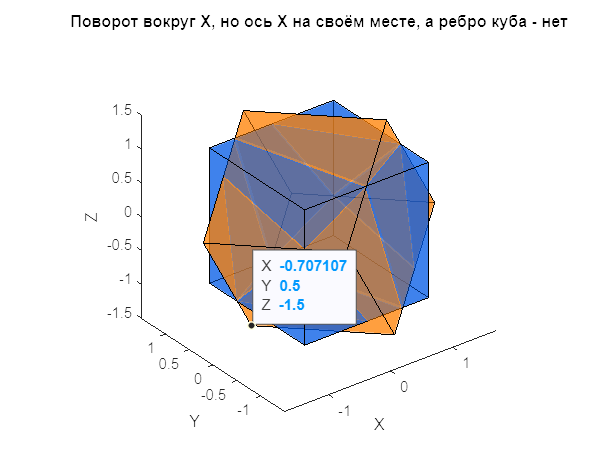

clf;
title('Поворот вокруг Х, но ось Х на своём месте, а ребро куба - нет');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube4 , facesCube , rgba);

ax6 = gca;
chart6 = ax6.Children(1);
datatip(chart6,-sin(alpha),0.49,-1.47);

Из этого можео сделать вывод, что повороты - отнюдь не самая простая штука, не обладающая 3D пространстве свойством коммутативности.

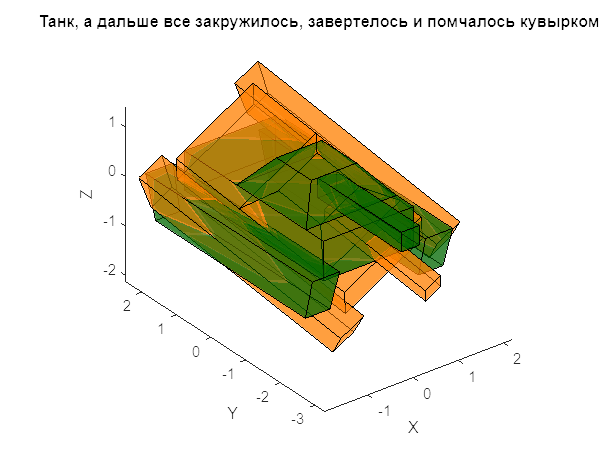

clf;title('Танк, а дальше все закружилось, завертелось и помчалось кувырком');Dshow ( TANK , faces ,greeen );Dshow ( A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * A4Y * A4X * TANK , faces , rgba );

*коллизию не прописывал

## Чтобы куб не крутился, я пригвоздил одну вершину

Вокруг неё он всё ещё может вращаться. Дабы не заниматься всякой слишком сложной математикой, вспомним, что мы уже умеем вращать кубы вокруг осей, умеем двигать кубы. Возьмем и сдвинем его так, чтобы спокойно вращать вокруг Ох, Оу, Оz, а потом поставим на место.

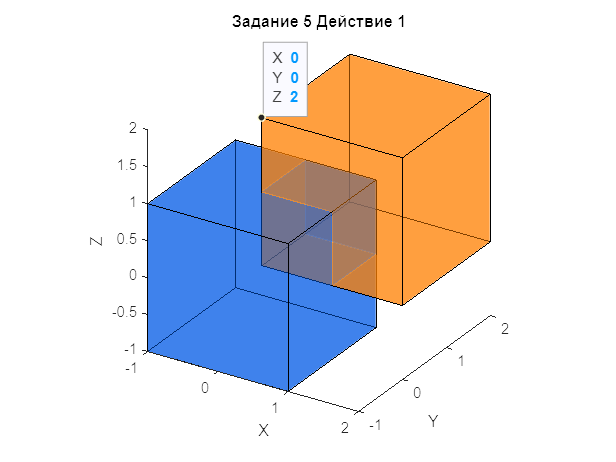

smesheie = [1;1;1;0];
Cube5 = Cube + smesheie;clf;
title('Задание 5 Действие 1');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax = gca;
chart = ax.Children(1);
datatip(chart,-2.274,-1.686,1.38);
ax4 = gca;
chart4 = ax4.Children(2);
datatip(chart4,-1,-1,1);

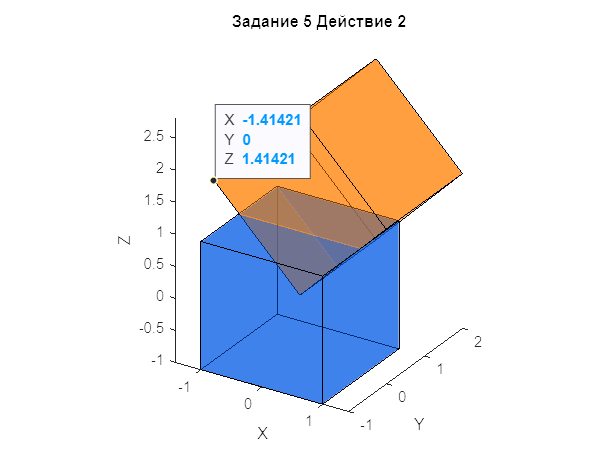

Cube5 = A4Y * Cube5;clf;
title('Задание 5 Действие 2');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax = gca;
chart = ax.Children(1);
datatip(chart,-2.274,-1.686,1.38);

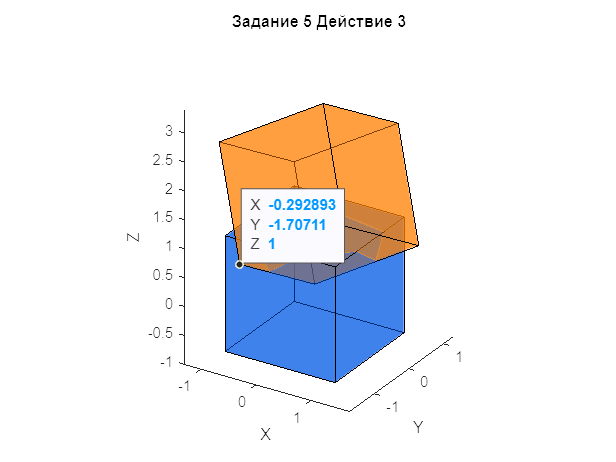


Cube5 = A4Z * A4X * Cube5;clf;
title('Задание 5 Действие 3');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,-0.294,-1.666,0.98);

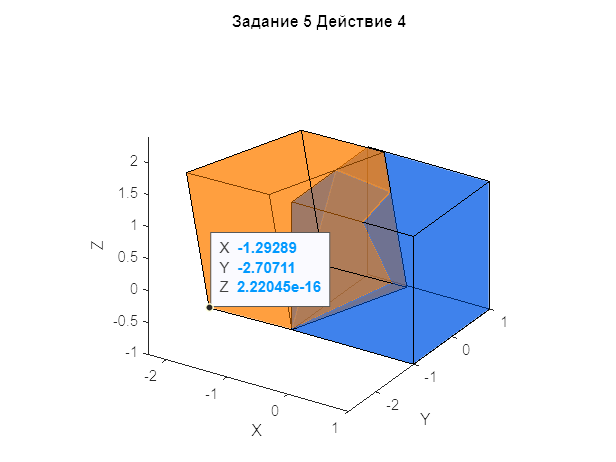


Cube5 = Cube5 - smesheie;clf;
title('Задание 5 Действие 4');

Dshow ( Cube , facesCube , blue);
Dshow ( Cube5 , facesCube , rgba);
view([32.03 27.00])
ax3 = gca;
chart3 = ax3.Children(1);
datatip(chart3,-1.294,-2.666,-0.02);

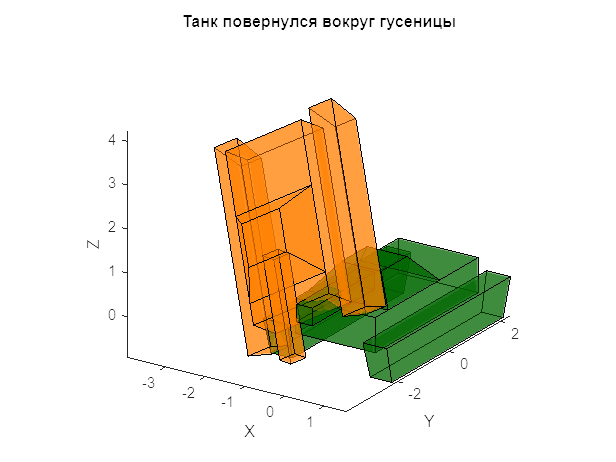

clf;title('Танк повернулся вокруг гусеницы');Dshow ( TANK , faces ,greeen );Dshow ( A4Z * A4X *A4Y * (TANK+[1.4;2.18;0.87;0]) - [1.4;2.18;0.87;0] , faces , rgba );view([32.91 22.20]);

Суть в том, что какая точка окажется в начале координат, воуруг такой вращать и будем.

## Такие красивые кубы, что хочется сфотографировать

Реализуем же камеру.

*Тут и на следующее в черновике была килотонна объяснений, но, экономя время читателя, не стану в финальной версии их приводить*

Смотреть будем из точки 5, 5, 2.5 в 000.

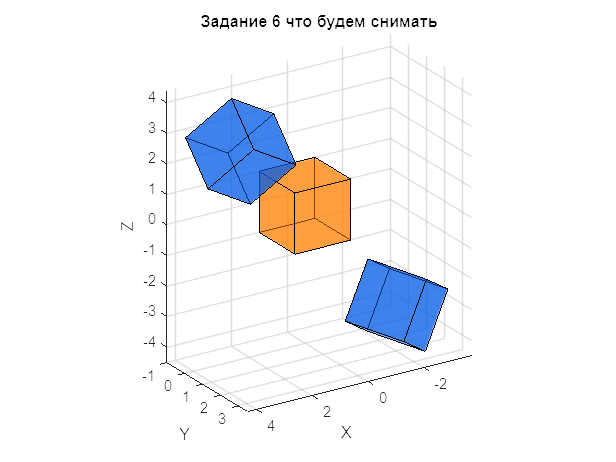

PosisionOfCUM=[5, 5, 2.5];DirectionOfCUM=[0, 0, 0];
camDir=(PosisionOfCUM-DirectionOfCUM)/norm(PosisionOfCUM-DirectionOfCUM);
camRight=cross([0, 1, 0], camDir)/norm(cross([0, 1, 0], camDir));
camUp=cross(camDir, camRight);
LookAt_1 = [camRight(1), camRight(2), camRight(3), 0;
    camUp(1), camUp(2), camUp(3), 0;
    camDir(1), camDir(2), camDir(3), 0;
    0, 0, 0, 1];
LookAt_2 = [1, 0, 0, -PosisionOfCUM(1);
    0, 1, 0, -PosisionOfCUM(2);
    0, 0, 1, -PosisionOfCUM(3);
    0, 0, 0, 1];
A6=LookAt_1*LookAt_2;
Cube61 = A6 * Cube;
smesheie62 = [3.6;2;2;0];
smesheie63 = [-2;2;-3;0];
Cube62 = Cube5 + smesheie62;clf;
Cube63 = Cube4 + smesheie63;clf;

title('Задание 6 что будем снимать');
Dshow ( Cube62 , facesCube , blue);
Dshow ( Cube63 , facesCube , blue);
Dshow ( Cube , facesCube , rgba);grid();
view([-205.08 53.51])

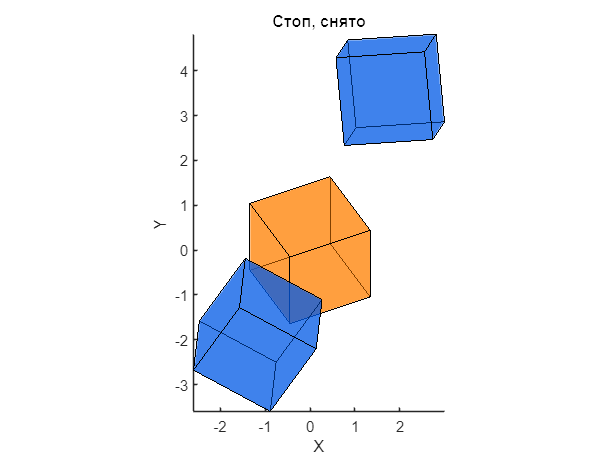

clf;title('Стоп, снято');
Dshow ( A6*Cube62 , facesCube , blue);
Dshow ( A6*Cube63 , facesCube , blue);
Dshow ( A6*Cube , facesCube , rgba);
view([0 90]);

Теперь по ГОСТу:

clf;PosisionOfCUM=[0, 0, 6];DirectionOfCUM=[0, 0, 0];
camDir=(PosisionOfCUM-DirectionOfCUM)/norm(PosisionOfCUM-DirectionOfCUM);
camRight=cross([0, 1, 0], camDir)/norm(cross([0, 1, 0], camDir));
camUp=cross(camDir, camRight);
LookAt_1 = [camRight(1), camRight(2), camRight(3), 0;
    camUp(1), camUp(2), camUp(3), 0;
    camDir(1), camDir(2), camDir(3), 0;
    0, 0, 0, 1];
LookAt_2 = [1, 0, 0, -PosisionOfCUM(1);
    0, 1, 0, -PosisionOfCUM(2);
    0, 0, 1, -PosisionOfCUM(3);
    0, 0, 0, 1];
A6=LookAt_1*LookAt_2;det(A6)

ans = 1

Если что, определитель матрицы камеры = 1, то есть она не искажает нам ничего.

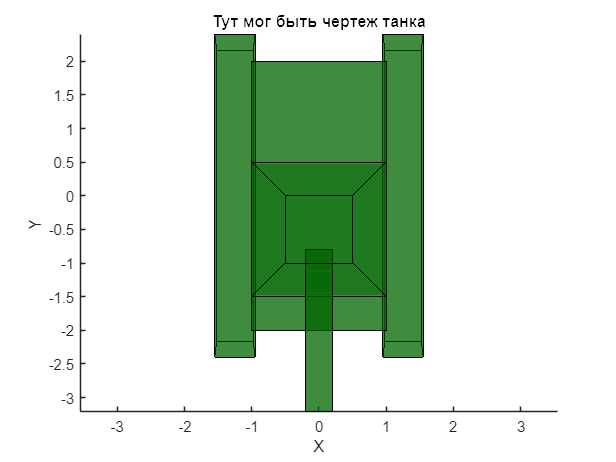

title('Тут мог быть чертеж танка');
Dshow ( A6*TANK , faces , greeen);view([0 90]);

[*В интерактивной версии можно покрутить](https://github.com/ne-umnepatop/PraktLinAlg/tree/main/%D0%9B%D0%B0%D0%B1%D0%BE%D1%80%D0%B0%D1%82%D0%BE%D1%80%D0%BD%D0%B0%D1%8F%20%D1%80%D0%B0%D0%B1%D0%BE%D1%82%D0%B0%203)

## Но нам не хватает явных перспектив

Путь поле зрения, оно же field of view, будет 90 градусов. Тогда:

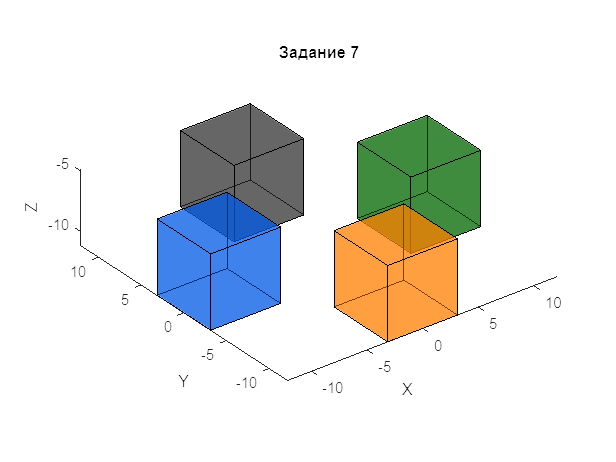

fov=90;f=150;n=0.1;
S = 1/(tan((fov/2)*(pi/180)));
A7=[S,0,0,0;
    0,S,0,0;
    0,0,(-f/(f-n)),-1;
    0,0,-(f*n)/(f-n),0];
clf;title('Задание 7');
Cube701=(Cube2+[9;0;-8;0]);Cube71=A7*Cube701;
Cube702=(Cube2+[-9;0;-8;0]);Cube72=A7*Cube702;
Cube703=(Cube2+[0;9;-8;0]);Cube73=A7*Cube703;
Cube704=(Cube2+[0;-9;-8;0]);Cube74=A7*Cube704;
Dshow ( Cube701 , facesCube , greeen);
Dshow ( Cube702 , facesCube , blue);
Dshow ( Cube703 , facesCube , bllk);
Dshow ( Cube704 , facesCube , rgba);clf;

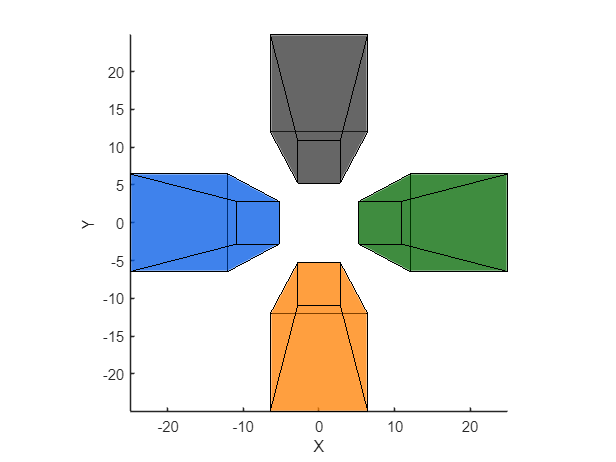

Dshow ( Cube71 , facesCube , greeen);
Dshow ( Cube72 , facesCube , blue);
Dshow ( Cube73 , facesCube , bllk);
Dshow ( Cube74 , facesCube , rgba);view([0, 90]);clf;

function DrawShape ( vertices , faces , color ) % принял набор координат вершин, 
% комбинации крайних точек граней, цвет
patch ("Vertices", ( vertices (1:3 ,:) ./ vertices (4 ,:))', "Faces", faces , ...
    "FaceAlpha", color(4), "FaceColor", color(1:3));
% разделили первые три координаты вершины на 4-ю за счёт ./ поэлементно
% это было на тот случай, если мы захотим рисовать под углом
% patch создало поверхность на этих вершинах,
% используя то описание граней и цвет
end

function Dshow ( verticesCube , facesCube , rgba )
DrawShape ( verticesCube , facesCube , rgba ) % вызвали отрисовку
xlabel('X');ylabel('Y');zlabel('Z');
axis equal; % чтобы была ДПСК
view (3); % смотрим в 3D
end